## **1. CoppeliaSim Initialization**

clear all; clc; close all;

sim = remApi('remoteApi');

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


sim.simxFinish(-1);
id = sim.simxStart('127.0.0.1', 19000, true, true, 5000, 5);

if id < 0
    disp('Connection failed!')
    sim.delete;
    sim_run_flag = 0;
    return;
else
    fprintf('Connection %d to remote API server is open!\n', id);
    [~, right_motor] = sim.simxGetObjectHandle(id, '/PioneerP3DX[0]/rightMotor',sim.simx_opmode_blocking);
    [~, left_motor] = sim.simxGetObjectHandle(id,'/PioneerP3DX[0]/leftMotor',sim.simx_opmode_blocking);
    [~, pioneer_p3dx] = sim.simxGetObjectHandle(id,'/PioneerP3DX[0]',sim.simx_opmode_blocking);
    [~, bill] = sim.simxGetObjectHandle(id,'/Bill[4]',sim.simx_opmode_blocking);
    for i = 1:5
        [~, disc{i}] = sim.simxGetObjectHandle(id, ['/Disc[', num2str(i-1), ']'], sim.simx_opmode_blocking);
    end
    
    for i=1:1:16
        [~,sensor(i)]=sim.simxGetObjectHandle(id, ['/PioneerP3DX[0]/ultrasonicSensor[', num2str(i-1), ']'], sim.simx_opmode_blocking);
    end

    for i=1:1:16
        [~,detect(i),distance(i,:),~,~]=sim.simxReadProximitySensor(id, sensor(i),sim.simx_opmode_streaming);
    end

    ret_codeR = sim.simxSetJointTargetVelocity(id, right_motor, 0.0, sim.simx_opmode_streaming);
    ret_codeL = sim.simxSetJointTargetVelocity(id, left_motor, 0.0, sim.simx_opmode_streaming);
    sim_run_flag = 1;
end

Connection 0 to remote API server is open!


## 2. Path Planning

#### Build the map

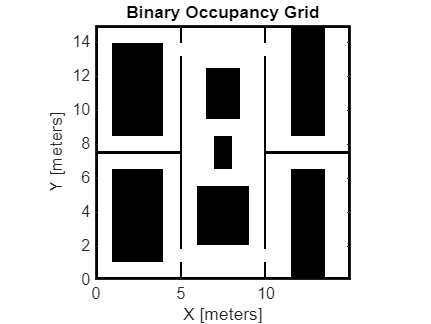

im_map = imread('Office-map.jpg');
im_bin = im2bw(im_map);
myMaplogical = not(logical(im_bin));
map = binaryOccupancyMap(myMaplogical, 433.0667);
show(map);

disp(map.DataSize)

        6496        6496



#### Build 

PRM = mobileRobotPRM(map, 1000);
show(PRM);

#### Find Path

if (sim_run_flag == 1)
    [~, pos]=sim.simxGetObjectPosition(id, pioneer_p3dx, -1, sim.simx_opmode_blocking);
    startPositionCoppelia = pos(1, 1:2);
    targetGoal = 5
    for i = 1:targetGoal
        [~, room{i}]=sim.simxGetObjectPosition(id, disc{i}, -1, sim.simx_opmode_blocking);
        roomPositionCoppelia{i} = room{i}(1, 1:2);
    end

end

targetGoal = 5


if (startPositionCoppelia == roomPositionCoppelia{1})
    disp(startPositionCoppelia);
    disp('Localization failed');
    sim_run_flag = 0;
else
    % Robot to People
    disp(startPositionCoppelia);
    disp(roomPositionCoppelia);
    pathGoal{1} = findpath(PRM, double (startPositionCoppelia), double (roomPositionCoppelia{1}));
    pathGoal{2} = findpath(PRM, double (roomPositionCoppelia{1}), double (roomPositionCoppelia{2}));
    pathGoal{3} = findpath(PRM, double (roomPositionCoppelia{2}), double (roomPositionCoppelia{3}));
    
    % Gabungkan jalur-jalur menjadi satu
    paths = {pathGoal{1}, pathGoal{2}, pathGoal{3}};
    completePath = [];

    for i = 0:length(paths)-1
        if ~isempty(paths{i+1}) % Adjusting index to access elements of the array
            % Gabungkan jalur, hindari duplikasi titik pertemuan
            if isempty(completePath)
                completePath = paths{i+1};
            else
                completePath = [completePath; paths{i+1}(2:end, :)];
            end
        else
            error(['No path found for segment ' num2str(i)]);
        end
    end
    % Robot to Homebase
    pathGoal{4} = findpath(PRM, double (roomPositionCoppelia{3}), double (roomPositionCoppelia{4}));
    pathGoal{5} = findpath(PRM, double (roomPositionCoppelia{4}), double (roomPositionCoppelia{5}));
    
    % Gabungkan jalur-jalur menjadi satu
    pathsHomebase = {pathGoal{4}, pathGoal{5}};
    completePathHomebase = [];

    for i = 1:length(pathsHomebase)
        if ~isempty(pathsHomebase{i}) % Adjusting index to access elements of the array
            % Gabungkan jalur, hindari duplikasi titik pertemuan
            if isempty(completePathHomebase)
                completePathHomebase = pathsHomebase{i};
            else
                completePathHomebase = [completePathHomebase; pathsHomebase{i}(2:end, :)];
            end
        else
            error(['No path found for segment ' num2str(i)]);
        end
    end

    % Menambahkan plot jalur perencanaan pergerakan ke dalam grafik
    hold on;
    plot(completePath(:,1), completePath(:,2), 'b-', 'LineWidth', 2);
    plot(completePathHomebase(:,1), completePathHomebase(:,2), 'r-', 'LineWidth', 2);
    hold off;
    title('Path Planning with Probabilistic Roadmap');
    legend('Planned Path');
    grid on;
end

   14.2903   14.3757



    {[14.2250 9.3750]}    {[1.3750 14.5250]}    {[6.9750 0.5000]}    {[8.0250 0.4750]}    {[9.0500 7.3750]}



## Path Tracking

if (sim_run_flag == 1)
    disp('Simulation is running');

####            Set the Pure Pursuit Control

    pp = controllerPurePursuit;

####            Init  goal reached status

    goalReachedCount = 0;
    reachedGoal = 0;
    count = 0;
    pathPlanning = 0;
    while goalReachedCount<3
        if(pathPlanning == 0)
            pp.Waypoints = completePath;
        end
        if(pathPlanning == 1)
            pp.Waypoints = completePathHomebase;
        end

####                   Get position and orientation of robot (Pose Sensing)

        [~, pos0]=sim.simxGetObjectPosition(id,pioneer_p3dx,-1,sim.simx_opmode_blocking);
        [~, ori]=sim.simxGetObjectOrientation(id,pioneer_p3dx,-1,sim.simx_opmode_blocking);
        [~, oriBill]=sim.simxGetObjectOrientation(id,bill,-1,sim.simx_opmode_blocking);
        currentPositionCoppelia = pos0(1,1:2);     
        currentOrientationCoppelia = ori(1,3);
        currentPoseCoppelia = [currentPositionCoppelia currentOrientationCoppelia];
        referenceOrientationPerson = oriBill(1,3); 

####                   Calculate the velocity of robot (Pure Pursuit)

        [v,w] = pp(currentPoseCoppelia);            

####                    Calculate the angular velocity for right and left wheel of robot (Inverse Kinematics)

        [phiR, phiL] = invkinem(v,w);

                    **Braitenberg Formula Calculation**

        point = [-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1];
        noDetectionDist=0.2;
        maxDetectionDist=0.1;
        detect=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
        braitenbergL=[-0.2 -0.4 -0.6 -0.8 -1.0 -1.2 -1.4 -1.6 0 0 0 0 0 0 0 0];
        braitenbergR=[-1.6 -1.4 -1.2 -1.0 -0.8 -0.6 -0.4 -0.2 0 0 0 0 0 0 0 0];
        
        for i=1:1:16
            [ret,detect(i),distance(i,:),~,~]=sim.simxReadProximitySensor(id, sensor(i),sim.simx_opmode_buffer);
            if(detect(i)==0)
                point(i)=1;
            else
                point(i)=norm(distance(i,:));
            end
        end

        for i=1:1:16
            distances=point(i);
            if(distances<noDetectionDist)
                if(distances<maxDetectionDist)
                    distances=maxDetectionDist;
                end
                    detect(i)=1-((distances-maxDetectionDist)/(noDetectionDist-maxDetectionDist));
            else
                detect(i)=0;
            end
        end

                    **Velocity Normalization**

        vnorm = 1.25;
        vmax = max(phiR, phiL);
        
        if(any(point < noDetectionDist))
            vright=vnorm + (braitenbergR(1)*detect(1)) + (braitenbergR(2)*detect(2)) + (braitenbergR(3)*detect(3)) + (braitenbergR(4)*detect(4)) + (braitenbergR(5)*detect(5)) + (braitenbergR(6)*detect(6)) + (braitenbergR(7)*detect(7)) + (braitenbergR(8)*detect(8));
            vleft=vnorm + (braitenbergL(1)*detect(1)) + (braitenbergL(2)*detect(2)) + (braitenbergL(3)*detect(3)) + (braitenbergL(4)*detect(4)) + (braitenbergL(5)*detect(5)) + (braitenbergL(6)*detect(6)) + (braitenbergL(7)*detect(7)) + (braitenbergL(8)*detect(8));    
            %This is the correct algorithm, 
            %but for some reason I try not to add up the Breitenberg constant and the detect variable
            %for i=1:16 
            %        vright=vnorm+braitenbergR(i)*detect(i);
            %        vleft=vnorm+braitenbergL(i)*detect(i);    
            %end
        else
            if vmax > vnorm
                vright = ((vnorm / vmax) * (phiR));
                vleft = ((vnorm / vmax) * (phiL));
            else
                vright = phiR;
                vleft = phiL
            end
        end
        

####                   Calculate the final angular velocity of robot wheels (Final Wheel Velocity Decision)

        goalPositionPeople = roomPositionCoppelia{3};
        distToGoalPeople = sqrt((currentPositionCoppelia(1)-goalPositionPeople(1))^2 + (currentPositionCoppelia(2)-goalPositionPeople(2))^2);

        goalPositionHomebase = roomPositionCoppelia{5};
        distToGoalHomebase = sqrt((currentPositionCoppelia(1)-goalPositionHomebase(1))^2 + (currentPositionCoppelia(2)-goalPositionHomebase(2))^2);
        
        if distToGoalPeople < 0.25 && pathPlanning == 0 
            vleft = 0.2 * (referenceOrientationPerson - currentOrientationCoppelia);
            vright = 0.2 * (referenceOrientationPerson + currentOrientationCoppelia);
            count = count+1;
        end
        
        if(count > 100)
            pathPlanning = 1;
        else
            pathPlanning = 0;
        end

        if distToGoalHomebase < 0.25 && pathPlanning == 1 
            vleft = 0;
            vright = 0;
        end
        
        velocity = [count, vleft, vright]
        disp(velocity);

####                   Send the final angular velocity of robot wheels to Pioneer P3DX  (Pioneer P3DX Robot)      

        ret_codeR = sim.simxSetJointTargetVelocity(id, right_motor, vright * 2, sim.simx_opmode_streaming);
        ret_codeL = sim.simxSetJointTargetVelocity(id, left_motor, vleft * 2, sim.simx_opmode_streaming);                        
    end 
    disp('Goal has been reached')
    sim.simxFinish(id);
end

Simulation is running


velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3 single row vector
         0    1.2500   -0.3514


         0    1.2500   -0.3514



velocity = 1×3 single row vector
         0    1.2500   -0.2878


         0    1.2500   -0.2878



velocity = 1×3 single row vector
         0    1.2500   -0.2148


         0    1.2500   -0.2148



velocity = 1×3 single row vector
         0    1.2500   -0.1315


         0    1.2500   -0.1315



velocity = 1×3 single row vector
         0    1.2500   -0.0536


         0    1.2500   -0.0536



velocity = 1×3 single row vector
         0    1.2500    0.0502


         0    1.2500    0.0502



velocity = 1×3 single row vector
         0    1.2500    0.1670


         0    1.2500    0.1670



velocity = 1×3 single row vector
         0    1.2500    0.2729


         0    1.2500    0.2729



velocity = 1×3 single row vector
         0    1.2500    0.4115


         0    1.2500    0.4115



velocity = 1×3 single row vector
         0    1.2500    0.5572


         0    1.2500    0.5572



velocity = 1×3 single row vector
         0    1.2500    0.7044


         0    1.2500    0.7044



vleft = single
1.2226

velocity = 1×3 single row vector
         0    1.2226    0.8287


         0    1.2226    0.8287



vleft = single
1.1622

velocity = 1×3 single row vector
         0    1.1622    0.8891


         0    1.1622    0.8891



vleft = single
1.1041

velocity = 1×3 single row vector
         0    1.1041    0.9472


         0    1.1041    0.9472



vleft = single
1.0693

velocity = 1×3 single row vector
         0    1.0693    0.9820


         0    1.0693    0.9820



vleft = single
1.0478

velocity = 1×3 single row vector
         0    1.0478    1.0034


         0    1.0478    1.0034



vleft = single
1.0345

velocity = 1×3 single row vector
         0    1.0345    1.0168


         0    1.0345    1.0168



vleft = single
1.0258

velocity = 1×3 single row vector
         0    1.0258    1.0255


         0    1.0258    1.0255



vleft = single
1.0196

velocity = 1×3 single row vector
         0    1.0196    1.0317


         0    1.0196    1.0317



vleft = single
1.0156

velocity = 1×3 single row vector
         0    1.0156    1.0357


         0    1.0156    1.0357



vleft = single
1.0128

velocity = 1×3 single row vector
         0    1.0128    1.0385


         0    1.0128    1.0385



vleft = single
1.0108

velocity = 1×3 single row vector
         0    1.0108    1.0405


         0    1.0108    1.0405



vleft = single
1.0095

velocity = 1×3 single row vector
         0    1.0095    1.0418


         0    1.0095    1.0418



vleft = single
1.0087

velocity = 1×3 single row vector
         0    1.0087    1.0426


         0    1.0087    1.0426



vleft = single
1.0082

velocity = 1×3 single row vector
         0    1.0082    1.0431


         0    1.0082    1.0431



vleft = single
1.0079

velocity = 1×3 single row vector
         0    1.0079    1.0434


         0    1.0079    1.0434



vleft = single
1.0078

velocity = 1×3
         0    1.0078    1.0435


         0    1.0078    1.0435



vleft = single
1.0078

velocity = 1×3
         0    1.0078    1.0434


         0    1.0078    1.0434



vleft = single
1.0080

velocity = 1×3
         0    1.0080    1.0433


         0    1.0080    1.0433



vleft = single
1.0081

velocity = 1×3
         0    1.0081    1.0432


         0    1.0081    1.0432



vleft = single
1.0082

velocity = 1×3
         0    1.0082    1.0430


         0    1.0082    1.0430



vleft = single
1.0084

velocity = 1×3
         0    1.0084    1.0428


         0    1.0084    1.0428



vleft = single
1.0086

velocity = 1×3
         0    1.0086    1.0427


         0    1.0086    1.0427



vleft = single
1.0088

velocity = 1×3
         0    1.0088    1.0425


         0    1.0088    1.0425



vleft = single
1.0090

velocity = 1×3
         0    1.0090    1.0423


         0    1.0090    1.0423



vleft = single
1.0093

velocity = 1×3
         0    1.0093    1.0420


         0    1.0093    1.0420



vleft = single
1.0094

velocity = 1×3
         0    1.0094    1.0419


         0    1.0094    1.0419



vleft = single
1.0095

velocity = 1×3
         0    1.0095    1.0417


         0    1.0095    1.0417



vleft = single
1.0098

velocity = 1×3
         0    1.0098    1.0415


         0    1.0098    1.0415



vleft = single
1.0100

velocity = 1×3
         0    1.0100    1.0413


         0    1.0100    1.0413



vleft = single
1.0102

velocity = 1×3
         0    1.0102    1.0411


         0    1.0102    1.0411



velocity = 1×3
         0    1.1643    1.1548


         0    1.1643    1.1548



velocity = 1×3
         0    0.8689    0.8306


         0    0.8689    0.8306



velocity = 1×3
         0    0.5751    0.4624


         0    0.5751    0.4624



velocity = 1×3
         0    0.3895    0.2359


         0    0.3895    0.2359



velocity = 1×3
         0    0.2422    0.0868


         0    0.2422    0.0868



velocity = 1×3
         0    0.1563   -0.0063


         0    0.1563   -0.0063



velocity = 1×3
         0    0.1242   -0.0473


         0    0.1242   -0.0473



velocity = 1×3
         0    0.1188   -0.0611


         0    0.1188   -0.0611



velocity = 1×3
         0    0.1230   -0.0678


         0    0.1230   -0.0678



velocity = 1×3
         0    0.1302   -0.0722


         0    0.1302   -0.0722



velocity = 1×3
         0    0.1389   -0.0759


         0    0.1389   -0.0759



velocity = 1×3
         0    0.1486   -0.0796


         0    0.1486   -0.0796



velocity = 1×3
         0    0.1593   -0.0831


         0    0.1593   -0.0831



velocity = 1×3
         0    0.1679   -0.0881


         0    0.1679   -0.0881



velocity = 1×3
         0    0.1631   -0.0999


         0    0.1631   -0.0999



velocity = 1×3
         0    0.1604   -0.1094


         0    0.1604   -0.1094



velocity = 1×3
         0    0.1604   -0.1155


         0    0.1604   -0.1155



velocity = 1×3
         0    0.1624   -0.1194


         0    0.1624   -0.1194



velocity = 1×3
         0    0.1657   -0.1218


         0    0.1657   -0.1218



velocity = 1×3
         0    0.1642   -0.1431


         0    0.1642   -0.1431



velocity = 1×3
         0    0.1631   -0.1655


         0    0.1631   -0.1655



velocity = 1×3
         0    0.1670   -0.1854


         0    0.1670   -0.1854



velocity = 1×3
         0    0.1733   -0.2032


         0    0.1733   -0.2032



velocity = 1×3
         0    0.1884   -0.2089


         0    0.1884   -0.2089



velocity = 1×3
         0    0.2052   -0.2192


         0    0.2052   -0.2192



velocity = 1×3
         0    0.2604   -0.1941


         0    0.2604   -0.1941



velocity = 1×3
         0    0.2565   -0.2251


         0    0.2565   -0.2251



velocity = 1×3
         0    0.2550   -0.2536


         0    0.2550   -0.2536



velocity = 1×3
         0    0.2628   -0.2749


         0    0.2628   -0.2749



velocity = 1×3
         0    0.2862   -0.2731


         0    0.2862   -0.2731



velocity = 1×3
         0    0.3167   -0.2690


         0    0.3167   -0.2690



velocity = 1×3
         0    0.3467   -0.2676


         0    0.3467   -0.2676



velocity = 1×3
         0    0.3767   -0.2688


         0    0.3767   -0.2688



velocity = 1×3
         0    0.4026   -0.2701


         0    0.4026   -0.2701



velocity = 1×3
         0    0.4356   -0.2717


         0    0.4356   -0.2717



velocity = 1×3
         0    0.4725   -0.2705


         0    0.4725   -0.2705



velocity = 1×3
         0    0.4711   -0.3002


         0    0.4711   -0.3002



velocity = 1×3
         0    0.4706   -0.3249


         0    0.4706   -0.3249



velocity = 1×3
         0    0.4771   -0.3364


         0    0.4771   -0.3364



velocity = 1×3
         0    0.4896   -0.3365


         0    0.4896   -0.3365



velocity = 1×3
         0    0.5422   -0.2839


         0    0.5422   -0.2839



velocity = 1×3
         0    0.5388   -0.3018


         0    0.5388   -0.3018



velocity = 1×3
         0    0.5407   -0.3132


         0    0.5407   -0.3132



velocity = 1×3
         0    0.5648   -0.2938


         0    0.5648   -0.2938



velocity = 1×3
         0    0.5869   -0.2750


         0    0.5869   -0.2750



velocity = 1×3
         0    0.6152   -0.2500


         0    0.6152   -0.2500



velocity = 1×3
         0    0.6430   -0.2390


         0    0.6430   -0.2390



velocity = 1×3
         0    0.6633   -0.3135


         0    0.6633   -0.3135



velocity = 1×3
         0    0.6974   -0.3599


         0    0.6974   -0.3599



velocity = 1×3
         0    0.7005   -0.4327


         0    0.7005   -0.4327



velocity = 1×3
         0    0.7043   -0.4797


         0    0.7043   -0.4797



velocity = 1×3
         0    0.7356   -0.4713


         0    0.7356   -0.4713



velocity = 1×3
         0    0.7387   -0.5102


         0    0.7387   -0.5102



velocity = 1×3
         0    0.7680   -0.4862


         0    0.7680   -0.4862



velocity = 1×3
         0    0.8051   -0.4367


         0    0.8051   -0.4367



velocity = 1×3
         0    0.8479   -0.3685


         0    0.8479   -0.3685



velocity = 1×3
         0    0.8962   -0.2817


         0    0.8962   -0.2817



velocity = 1×3
         0    0.9493   -0.1785


         0    0.9493   -0.1785



velocity = 1×3
         0    0.9862   -0.0822


         0    0.9862   -0.0822



velocity = 1×3
         0    0.9823   -0.1020


         0    0.9823   -0.1020



velocity = 1×3
         0    0.9934   -0.0649


         0    0.9934   -0.0649



velocity = 1×3
         0    1.0087   -0.0093


         0    1.0087   -0.0093



velocity = 1×3
         0    1.0264    0.0569


         0    1.0264    0.0569



velocity = 1×3
         0    1.0460    0.1319


         0    1.0460    0.1319



velocity = 1×3
         0    1.0671    0.2138


         0    1.0671    0.2138



velocity = 1×3
         0    1.0899    0.3041


         0    1.0899    0.3041



velocity = 1×3
         0    1.1138    0.3998


         0    1.1138    0.3998



velocity = 1×3
         0    1.1383    0.4975


         0    1.1383    0.4975



velocity = 1×3
         0    1.1633    0.5997


         0    1.1633    0.5997



velocity = 1×3
         0    1.1763    0.6604


         0    1.1763    0.6604



velocity = 1×3
         0    1.1800    0.6899


         0    1.1800    0.6899



velocity = 1×3
         0    1.1839    0.7216


         0    1.1839    0.7216



velocity = 1×3
         0    1.1882    0.7557


         0    1.1882    0.7557



velocity = 1×3
         0    1.1936    0.7985


         0    1.1936    0.7985



velocity = 1×3
         0    1.1968    0.8245


         0    1.1968    0.8245



velocity = 1×3
         0    1.2010    0.8582


         0    1.2010    0.8582



velocity = 1×3
         0    1.2063    0.9005


         0    1.2063    0.9005



velocity = 1×3
         0    1.2118    0.9443


         0    1.2118    0.9443



velocity = 1×3
         0    1.2174    0.9894


         0    1.2174    0.9894



velocity = 1×3
         0    1.2232    1.0358


         0    1.2232    1.0358



velocity = 1×3
         0    1.2291    1.0828


         0    1.2291    1.0828



velocity = 1×3
         0    1.2331    1.1145


         0    1.2331    1.1145



velocity = 1×3
         0    1.2390    1.1619


         0    1.2390    1.1619



velocity = 1×3
         0    1.2449    1.2095


         0    1.2449    1.2095



velocity = 1×3
         0    1.2498    1.2488


         0    1.2498    1.2488



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0    1.2433    1.2264


         0    1.2433    1.2264



velocity = 1×3
         0    1.2270    1.1697


         0    1.2270    1.1697



velocity = 1×3
         0    1.2129    1.1202


         0    1.2129    1.1202



velocity = 1×3
         0    1.1813    1.0284


         0    1.1813    1.0284



velocity = 1×3
         0    1.1164    0.8658


         0    1.1164    0.8658



velocity = 1×3
         0    1.0505    0.6969


         0    1.0505    0.6969



velocity = 1×3
         0    0.9858    0.5277


         0    0.9858    0.5277



velocity = 1×3
         0    0.9319    0.3839


         0    0.9319    0.3839



velocity = 1×3
         0    0.8793    0.1877


         0    0.8793    0.1877



velocity = 1×3
         0    0.8353   -0.0115


         0    0.8353   -0.0115



velocity = 1×3
         0    0.8100   -0.1530


         0    0.8100   -0.1530



velocity = 1×3
         0    0.8006   -0.2456


         0    0.8006   -0.2456



velocity = 1×3
         0    0.8055   -0.2946


         0    0.8055   -0.2946



velocity = 1×3
         0    0.8209   -0.3113


         0    0.8209   -0.3113



velocity = 1×3
         0    0.8453   -0.2998


         0    0.8453   -0.2998



velocity = 1×3
         0    0.8777   -0.2630


         0    0.8777   -0.2630



velocity = 1×3
         0    0.9176   -0.2014


         0    0.9176   -0.2014



velocity = 1×3
         0    0.9635   -0.1200


         0    0.9635   -0.1200



velocity = 1×3
         0    0.9798   -0.0912


         0    0.9798   -0.0912



velocity = 1×3
         0    0.9875   -0.0720


         0    0.9875   -0.0720



velocity = 1×3
         0    0.9984   -0.0370


         0    0.9984   -0.0370



velocity = 1×3
         0    1.0121    0.0114


         0    1.0121    0.0114



velocity = 1×3
         0    1.0283    0.0719


         0    1.0283    0.0719



velocity = 1×3
         0    1.0466    0.1408


         0    1.0466    0.1408



velocity = 1×3
         0    1.0661    0.2160


         0    1.0661    0.2160



velocity = 1×3
         0    1.0838    0.2847


         0    1.0838    0.2847



velocity = 1×3
         0    1.1058    0.3718


         0    1.1058    0.3718



velocity = 1×3
         0    1.1292    0.4656


         0    1.1292    0.4656



velocity = 1×3
         0    1.1533    0.5632


         0    1.1533    0.5632



velocity = 1×3
         0    1.1736    0.6461


         0    1.1736    0.6461



velocity = 1×3
         0    1.1786    0.6785


         0    1.1786    0.6785



velocity = 1×3
         0    1.1822    0.7076


         0    1.1822    0.7076



velocity = 1×3
         0    1.1862    0.7397


         0    1.1862    0.7397



velocity = 1×3
         0    1.1898    0.7681


         0    1.1898    0.7681



velocity = 1×3
         0    1.1935    0.7980


         0    1.1935    0.7980



velocity = 1×3
         0    1.1983    0.8361


         0    1.1983    0.8361



velocity = 1×3
         0    1.2032    0.8760


         0    1.2032    0.8760



velocity = 1×3
         0    1.2085    0.9177


         0    1.2085    0.9177



velocity = 1×3
         0    1.2148    0.9681


         0    1.2148    0.9681



velocity = 1×3
         0    1.2194    1.0049


         0    1.2194    1.0049



velocity = 1×3
         0    1.2250    1.0500


         0    1.2250    1.0500



velocity = 1×3
         0    1.2307    1.0959


         0    1.2307    1.0959



velocity = 1×3
         0    1.2365    1.1421


         0    1.2365    1.1421



velocity = 1×3
         0    1.2423    1.1883


         0    1.2423    1.1883



velocity = 1×3
         0    1.2481    1.2345


         0    1.2481    1.2345



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0    1.2424    1.2233


         0    1.2424    1.2233



velocity = 1×3
         0    1.2255    1.1643


         0    1.2255    1.1643



velocity = 1×3
         0    1.2104    1.1114


         0    1.2104    1.1114



velocity = 1×3
         0    1.1819    1.0248


         0    1.1819    1.0248



velocity = 1×3
         0    1.1155    0.8586


         0    1.1155    0.8586



velocity = 1×3
         0    1.0501    0.6912


         0    1.0501    0.6912



velocity = 1×3
         0    0.9883    0.5297


         0    0.9883    0.5297



velocity = 1×3
         0    0.9372    0.3931


         0    0.9372    0.3931



velocity = 1×3
         0    0.8846    0.1712


         0    0.8846    0.1712



velocity = 1×3
         0    0.8388   -0.0418


         0    0.8388   -0.0418



velocity = 1×3
         0    0.8222   -0.1442


         0    0.8222   -0.1442



velocity = 1×3
         0    0.8172   -0.2115


         0    0.8172   -0.2115



velocity = 1×3
         0    0.8227   -0.2578


         0    0.8227   -0.2578



velocity = 1×3
         0    0.8377   -0.2747


         0    0.8377   -0.2747



velocity = 1×3
         0    0.8604   -0.2673


         0    0.8604   -0.2673



velocity = 1×3
         0    0.8906   -0.2359


         0    0.8906   -0.2359



velocity = 1×3
         0    0.9286   -0.1768


         0    0.9286   -0.1768



velocity = 1×3
         0    0.9817   -0.0490


         0    0.9817   -0.0490



velocity = 1×3
         0    0.9789   -0.0983


         0    0.9789   -0.0983



velocity = 1×3
         0    0.9863   -0.0803


         0    0.9863   -0.0803



velocity = 1×3
         0    0.9978   -0.0423


         0    0.9978   -0.0423



velocity = 1×3
         0    1.0122    0.0094


         0    1.0122    0.0094



velocity = 1×3
         0    1.0287    0.0703


         0    1.0287    0.0703



velocity = 1×3
         0    1.0472    0.1400


         0    1.0472    0.1400



velocity = 1×3
         0    1.0672    0.2171


         0    1.0672    0.2171



velocity = 1×3
         0    1.0891    0.3032


         0    1.0891    0.3032



velocity = 1×3
         0    1.1125    0.3962


         0    1.1125    0.3962



velocity = 1×3
         0    1.1327    0.4772


         0    1.1327    0.4772



velocity = 1×3
         0    1.1569    0.5757


         0    1.1569    0.5757



velocity = 1×3
         0    1.1758    0.6568


         0    1.1758    0.6568



velocity = 1×3
         0    1.1794    0.6848


         0    1.1794    0.6848



velocity = 1×3
         0    1.1832    0.7157


         0    1.1832    0.7157



velocity = 1×3
         0    1.1875    0.7500


         0    1.1875    0.7500



velocity = 1×3
         0    1.1912    0.7799


         0    1.1912    0.7799



velocity = 1×3
         0    1.1960    0.8180


         0    1.1960    0.8180



velocity = 1×3
         0    1.2010    0.8577


         0    1.2010    0.8577



velocity = 1×3
         0    1.2061    0.8988


         0    1.2061    0.8988



velocity = 1×3
         0    1.2114    0.9414


         0    1.2114    0.9414



velocity = 1×3
         0    1.2169    0.9855


         0    1.2169    0.9855



velocity = 1×3
         0    1.2226    1.0305


         0    1.2226    1.0305



velocity = 1×3
         0    1.2283    1.0764


         0    1.2283    1.0764



velocity = 1×3
         0    1.2331    1.1150


         0    1.2331    1.1150



velocity = 1×3
         0    1.2380    1.1538


         0    1.2380    1.1538



velocity = 1×3
         0    1.2438    1.2004


         0    1.2438    1.2004



velocity = 1×3
         0    1.2486    1.2389


         0    1.2486    1.2389



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0   -0.1681    1.2500


         0   -0.1681    1.2500



velocity = 1×3
         0   -0.1630    1.2500


         0   -0.1630    1.2500



velocity = 1×3
         0   -0.1722    1.2500


         0   -0.1722    1.2500



velocity = 1×3
         0   -0.1966    1.2500


         0   -0.1966    1.2500



velocity = 1×3
         0   -0.2340    1.2500


         0   -0.2340    1.2500



velocity = 1×3
         0   -0.2834    1.2500


         0   -0.2834    1.2500



velocity = 1×3
         0   -0.3274    1.2500


         0   -0.3274    1.2500



velocity = 1×3
         0   -0.3710    1.2500


         0   -0.3710    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0    1.2479    1.2427


         0    1.2479    1.2427



velocity = 1×3
         0    1.2342    1.1946


         0    1.2342    1.1946



velocity = 1×3
         0    1.2170    1.1345


         0    1.2170    1.1345



velocity = 1×3
         0    1.1980    1.0681


         0    1.1980    1.0681



velocity = 1×3
         0    1.1508    0.9398


         0    1.1508    0.9398



velocity = 1×3
         0    1.0837    0.7682


         0    1.0837    0.7682



velocity = 1×3
         0    1.0205    0.6029


         0    1.0205    0.6029



velocity = 1×3
         0    0.9608    0.4095


         0    0.9608    0.4095



velocity = 1×3
         0    0.9046    0.1765


         0    0.9046    0.1765



velocity = 1×3
         0    0.8704    0.0210


         0    0.8704    0.0210



velocity = 1×3
         0    0.8509   -0.1000


         0    0.8509   -0.1000



velocity = 1×3
         0    0.8465   -0.1748


         0    0.8465   -0.1748



velocity = 1×3
         0    0.8550   -0.2099


         0    0.8550   -0.2099



velocity = 1×3
         0    0.8736   -0.2131


         0    0.8736   -0.2131



velocity = 1×3
         0    0.8998   -0.1927


         0    0.8998   -0.1927



velocity = 1×3
         0    0.9332   -0.1491


         0    0.9332   -0.1491



velocity = 1×3
         0    0.9725   -0.0861


         0    0.9725   -0.0861



velocity = 1×3
         0    0.9828   -0.0742


         0    0.9828   -0.0742



velocity = 1×3
         0    0.9892   -0.0610


         0    0.9892   -0.0610



velocity = 1×3
         0    0.9992   -0.0302


         0    0.9992   -0.0302



velocity = 1×3
         0    1.0122    0.0151


         0    1.0122    0.0151



velocity = 1×3
         0    1.0275    0.0707


         0    1.0275    0.0707



velocity = 1×3
         0    1.0453    0.1378


         0    1.0453    0.1378



velocity = 1×3
         0    1.0652    0.2142


         0    1.0652    0.2142



velocity = 1×3
         0    1.0830    0.2841


         0    1.0830    0.2841



velocity = 1×3
         0    1.1012    0.3557


         0    1.1012    0.3557



velocity = 1×3
         0    1.1238    0.4460


         0    1.1238    0.4460



velocity = 1×3
         0    1.1471    0.5395


         0    1.1471    0.5395



velocity = 1×3
         0    1.1707    0.6359


         0    1.1707    0.6359



velocity = 1×3
         0    1.1785    0.6780


         0    1.1785    0.6780



velocity = 1×3
         0    1.1820    0.7063


         0    1.1820    0.7063



velocity = 1×3
         0    1.1859    0.7376


         0    1.1859    0.7376



velocity = 1×3
         0    1.1894    0.7653


         0    1.1894    0.7653



velocity = 1×3
         0    1.1938    0.8006


         0    1.1938    0.8006



velocity = 1×3
         0    1.1985    0.8383


         0    1.1985    0.8383



velocity = 1×3
         0    1.2035    0.8781


         0    1.2035    0.8781



velocity = 1×3
         0    1.2087    0.9195


         0    1.2087    0.9195



velocity = 1×3
         0    1.2141    0.9626


         0    1.2141    0.9626



velocity = 1×3
         0    1.2196    1.0068


         0    1.2196    1.0068



velocity = 1×3
         0    1.2252    1.0519


         0    1.2252    1.0519



velocity = 1×3
         0    1.2310    1.0979


         0    1.2310    1.0979



velocity = 1×3
         0    1.2358    1.1362


         0    1.2358    1.1362



velocity = 1×3
         0    1.2415    1.1824


         0    1.2415    1.1824



velocity = 1×3
         0    1.2473    1.2283


         0    1.2473    1.2283



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0   -0.2137    1.2500


         0   -0.2137    1.2500



velocity = 1×3
         0   -0.2158    1.2500


         0   -0.2158    1.2500



velocity = 1×3
         0   -0.2067    1.2500


         0   -0.2067    1.2500



velocity = 1×3
         0   -0.1825    1.2500


         0   -0.1825    1.2500



velocity = 1×3
         0   -0.1387    1.2500


         0   -0.1387    1.2500



velocity = 1×3
         0   -0.0716    1.2500


         0   -0.0716    1.2500



velocity = 1×3
         0    0.0032    1.2500


         0    0.0032    1.2500



velocity = 1×3
         0    0.1046    1.2500


         0    0.1046    1.2500



velocity = 1×3
         0    0.2267    1.2500


         0    0.2267    1.2500



velocity = 1×3
         0    0.3339    1.2500


         0    0.3339    1.2500



velocity = 1×3
         0    0.4707    1.2500


         0    0.4707    1.2500



velocity = 1×3
         0    0.6084    1.2500


         0    0.6084    1.2500



velocity = 1×3
         0    0.7199    1.2500


         0    0.7199    1.2500



vleft = single
0.8254

velocity = 1×3
         0    0.8254    1.2259


         0    0.8254    1.2259



vleft = single
0.8881

velocity = 1×3
         0    0.8881    1.1632


         0    0.8881    1.1632



vleft = single
0.9381

velocity = 1×3
         0    0.9381    1.1132


         0    0.9381    1.1132



vleft = single
0.9718

velocity = 1×3
         0    0.9718    1.0795


         0    0.9718    1.0795



vleft = single
0.9917

velocity = 1×3
         0    0.9917    1.0596


         0    0.9917    1.0596



vleft = single
1.0034

velocity = 1×3
         0    1.0034    1.0479


         0    1.0034    1.0479



vleft = single
1.0102

velocity = 1×3
         0    1.0102    1.0411


         0    1.0102    1.0411



vleft = single
1.0144

velocity = 1×3
         0    1.0144    1.0369


         0    1.0144    1.0369



vleft = single
1.0174

velocity = 1×3
         0    1.0174    1.0339


         0    1.0174    1.0339



vleft = single
1.0197

velocity = 1×3
         0    1.0197    1.0316


         0    1.0197    1.0316



vleft = single
1.0214

velocity = 1×3
         0    1.0214    1.0299


         0    1.0214    1.0299



velocity = 1×3
         0    1.2461    1.2185


         0    1.2461    1.2185



velocity = 1×3
         0    1.2405    1.1743


         0    1.2405    1.1743



velocity = 1×3
         0    1.2358    1.1364


         0    1.2358    1.1364



velocity = 1×3
         0    1.2295    1.0901


         0    1.2295    1.0901



velocity = 1×3
         0    1.2158    1.0195


         0    1.2158    1.0195



velocity = 1×3
         0    1.2077    0.9771


         0    1.2077    0.9771



velocity = 1×3
         0    1.1980    0.9242


         0    1.1980    0.9242



velocity = 1×3
         0    1.1902    0.8796


         0    1.1902    0.8796



velocity = 1×3
         0    1.1845    0.8448


         0    1.1845    0.8448



velocity = 1×3
         0    1.1808    0.8190


         0    1.1808    0.8190



velocity = 1×3
         0    1.1791    0.8021


         0    1.1791    0.8021



velocity = 1×3
         0    1.1790    0.7929


         0    1.1790    0.7929



velocity = 1×3
         0    1.1806    0.7914


         0    1.1806    0.7914



velocity = 1×3
         0    1.1838    0.7971


         0    1.1838    0.7971



velocity = 1×3
         0    1.1883    0.8090


         0    1.1883    0.8090



velocity = 1×3
         0    1.1940    0.8269


         0    1.1940    0.8269



sim.delete(); % call the destructor! 
if (sim_run_flag == 1)
    beep;
    disp('Simulation successful');
else
    beep;pause(1);beep;
    disp('Simulation unsuccessful');
end
disp('Program ended');  

## Functions Definition

function [pR,pL] = invkinem(v,w)
% INVKINEM Inverse kinematics for Pioneer P3DX Diffrerential Steering Robot
    wheelradius = 0.195/2;
    bodywidth = 0.381;
    R2 = wheelradius/2;
    RB = wheelradius/bodywidth;
    vw = [v;w];
    kinemat = [R2 R2; RB -RB];
    pLR = kinemat\vw;
    pR = pLR(1);
    pL = pLR(2);
end